# **Modulation**

## **Wireless Communications: Performance Analysis Verification via Monte Carlo Simulations**

Author: Albedo (Zheyu Wang)

Created Date: 06.06.2025

Last Modified: 18.06.2025

Clarification: *'Albedo' is an informal English name adopted by the author due to the phonetic difficulty of the given name 'Zheyu'.*

### **Read Me**

This script provides a supplementary demonstration of how different digital modulation schemes (BPSK, QPSK, 8PSK) and channel equalization techniques can affect the performance of a communication system under additive white Gaussian noise (AWGN) and simple fading conditions.

Although modulation and equalization are not the core focus of this report, they are fundamental to understanding overall system behavior and are therefore included here to support broader context and insights.

#### 1 Constellation

This MATLAB script simulates and visualizes BPSK, QPSK, and 8PSK constellations under AWGN for a given SNR. It shows both the ideal constellation points and the received noisy symbols to illustrate modulation performance.

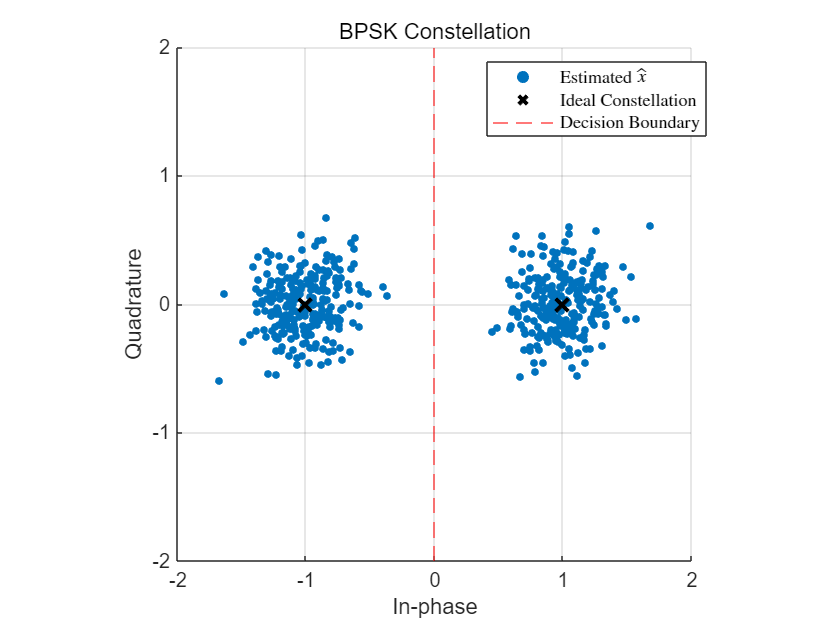

%% Common Parameter Settings
N = 500;                         % Number of symbols
EbN0_dB = 10;                    % SNR in dB
EbN0 = 10^(EbN0_dB / 10);        % Linear SNR
N0 = 1;                          % Noise power spectral density
Eb = EbN0 * N0;                  % Energy per bit
noise = sqrt(N0/2) * (randn(1,N) + 1j*randn(1,N));  % AWGN (complex)

%% Modulation Energy and Mapping Definitions
% BPSK
M_bpsk = 2;
Es_bpsk = Eb * log2(M_bpsk);
bpsk_map = [-1, 1];

% QPSK
M_qpsk = 4;
Es_qpsk = Eb * log2(M_qpsk);
qpsk_map = [1+1j, -1+1j, -1-1j, 1-1j] / sqrt(2);  % Unit-energy

% 8PSK
M_8psk = 8;
Es_8psk = Eb * log2(M_8psk);
psk8_map = exp(1j * 2 * pi * (0:M_8psk-1)/M_8psk);  % Unit circle mapping

%% ---------- BPSK Simulation ----------
x_bpsk = randi([0 1], 1, N);                      % Random bits
s_bpsk = sqrt(Es_bpsk) * (2 * x_bpsk - 1);        % BPSK modulation
r_bpsk = s_bpsk + noise;                          % Received signal
x_hat_bpsk = r_bpsk / sqrt(Es_bpsk);              % Normalize

figure;
scatter(real(x_hat_bpsk), imag(x_hat_bpsk), 15, 'filled', 'DisplayName', 'Estimated $\hat{x}$'); hold on;
scatter(bpsk_map, [0 0], 80, 'kx', 'LineWidth', 2, 'DisplayName', 'Ideal Constellation');
xline(0, '--r', 'DisplayName', 'Decision Boundary');
legend('Location', 'best', 'Interpreter', 'latex');
title('BPSK Constellation');
xlabel('In-phase'); ylabel('Quadrature');
axis equal; xlim([-2 2]); ylim([-2 2]); xticks(-2:1:2); yticks(-2:1:2); grid on;

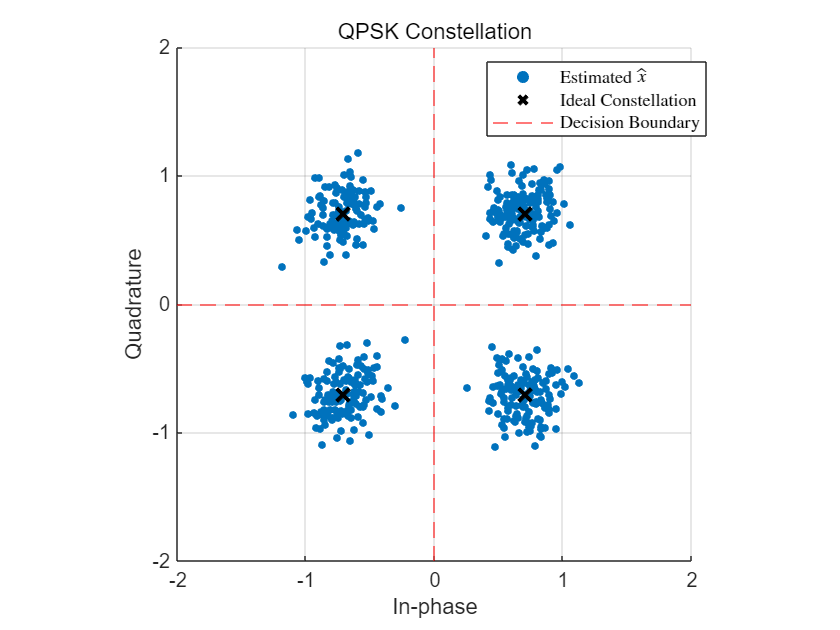


%% ---------- QPSK Simulation ----------
x_qpsk_idx = randi([1 M_qpsk], 1, N);                  % Symbol indices
s_qpsk = sqrt(Es_qpsk) * qpsk_map(x_qpsk_idx);         % QPSK modulation
r_qpsk = s_qpsk + noise;                               % Received signal
x_hat_qpsk = r_qpsk / sqrt(Es_qpsk);                   % Normalize

figure;
scatter(real(x_hat_qpsk), imag(x_hat_qpsk), 15, 'filled', 'DisplayName', 'Estimated $\hat{x}$'); hold on;
scatter(real(qpsk_map), imag(qpsk_map), 80, 'kx', 'LineWidth', 2, 'DisplayName', 'Ideal Constellation');
xline(0, '--r', 'HandleVisibility', 'off');
yline(0, '--r', 'DisplayName', 'Decision Boundary');
legend('Location', 'best', 'Interpreter', 'latex');
title('QPSK Constellation');
xlabel('In-phase'); ylabel('Quadrature');
axis equal; xlim([-2 2]); ylim([-2 2]); xticks(-2:1:2); yticks(-2:1:2); grid on;

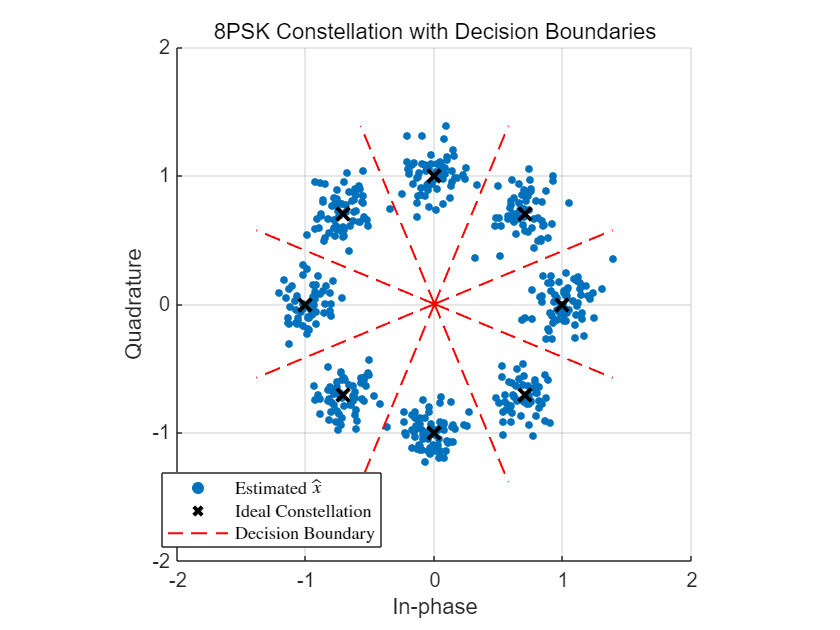


%% ---------- 8PSK Simulation ----------
x_8psk_idx = randi([1 M_8psk], 1, N);               % Symbol indices
s_8psk = sqrt(Es_8psk) * psk8_map(x_8psk_idx);      % 8PSK modulation
r_8psk = s_8psk + noise;                            % Received signal
x_hat_8psk = r_8psk / sqrt(Es_8psk);                % Normalize

figure;
scatter(real(x_hat_8psk), imag(x_hat_8psk), 15, 'filled', 'DisplayName', 'Estimated $\hat{x}$'); hold on;
scatter(real(psk8_map), imag(psk8_map), 80, 'kx', 'LineWidth', 2, 'DisplayName', 'Ideal Constellation');

% Decision boundary lines (theoretical)
theta_boundary = pi/M_8psk + (0:M_8psk-1)*2*pi/M_8psk;
plot([0 cos(theta_boundary(1))]*1.5, [0 sin(theta_boundary(1))]*1.5, '--r', 'LineWidth', 1, 'DisplayName', 'Decision Boundary');  
for i = 2:length(theta_boundary)
    angle = theta_boundary(i);
    plot([0 cos(angle)]*1.5, [0 sin(angle)]*1.5, '--r', 'LineWidth', 1, 'HandleVisibility', 'off');
end

legend('Location', 'best', 'Interpreter', 'latex');
title('8PSK Constellation with Decision Boundaries');
xlabel('In-phase'); ylabel('Quadrature');
axis equal; xlim([-2 2]); ylim([-2 2]); xticks(-2:1:2); yticks(-2:1:2); grid on;

#### 2 Channel Equalization

This MATLAB code simulates a QPSK communication system over a per-symbol rotating phase channel with additive Gaussian noise. It visualizes the received constellation points before and after channel equalization compared to the ideal constellation.

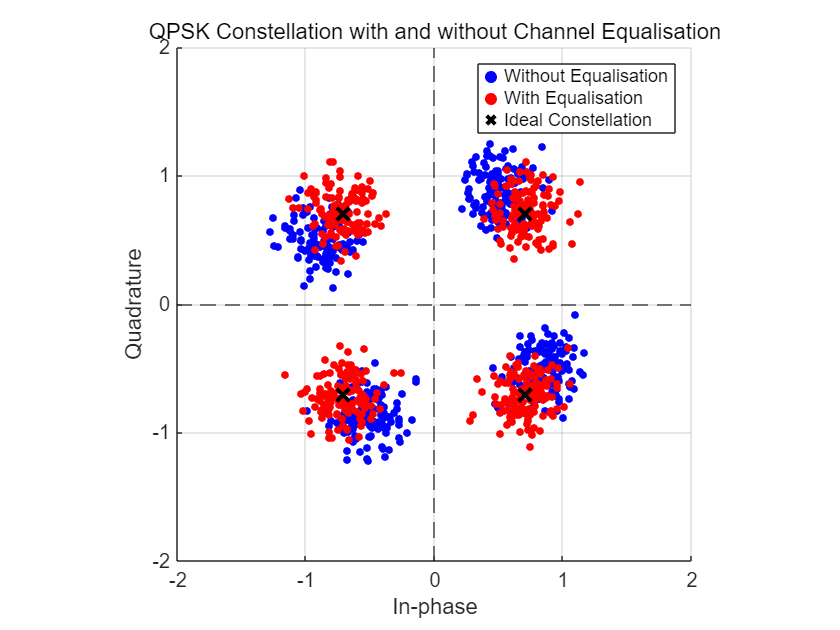

%% Parameter Settings
N = 500;                  % Number of symbols
EbN0_dB = 10;             % SNR in dB
EbN0 = 10^(EbN0_dB / 10); % Linear SNR
N0 = 1;                   % Noise power spectral density
k = 2;                    % Bits per symbol (QPSK -> 2 bits)
Es = k * EbN0 * N0;       % Symbol energy Es = k * Eb
noise = sqrt(N0/2) * (randn(1,N) + 1j*randn(1,N));  % Complex Gaussian noise

%% QPSK Modulation Mapping (Unit Energy)
qpsk_map = [1+1j, -1+1j, -1-1j, 1-1j] / sqrt(2);  % QPSK constellation

% Random bit mapping to QPSK symbols
x_idx = randi([1 4], 1, N);     % Random indices
x = qpsk_map(x_idx);           % Transmitted symbols (unit energy)
s = sqrt(Es) * x;              % Scaled transmit signal (with symbol energy)

%% Channel Modeling: Per-symbol Rotation Fading
theta_deg = 12 + (17 - 12) * rand(1, N);       % Random rotation angle per symbol (in degrees)
h = exp(1j * deg2rad(theta_deg));              % Complex channel gain (rotation only)

%% Received Signal
r = h .* s + noise;            % Received signal with channel effect and noise

%% Signal Estimation
x_hat_no_eq = r / sqrt(Es);          % Without channel equalization (only normalize energy)
x_hat_eq = r ./ h / sqrt(Es);        % With channel equalization (recover original symbols)

%% Plotting
figure;
scatter(real(x_hat_no_eq), imag(x_hat_no_eq), 15, 'b', 'filled'); hold on;
scatter(real(x_hat_eq), imag(x_hat_eq), 15, 'r', 'filled');
scatter(real(qpsk_map), imag(qpsk_map), 80, 'kx', 'LineWidth', 2);  % Ideal constellation
xline(0, '--k'); yline(0, '--k');
legend('Without Equalisation', 'With Equalisation', 'Ideal Constellation');
title('QPSK Constellation with and without Channel Equalisation');
xlabel('In-phase'); ylabel('Quadrature');
axis equal; xlim([-2 2]); ylim([-2 2]);
xticks(-2:1:2); yticks(-2:1:2); grid on;